# Homework #7: Due 11:59PM (EST), Friday, April 23

## Problem 1: Newton's ODE (20 points)

One of the earliest examples of an ordinary differential equation is from Newton (1671):


$$\frac{dx}{dt}=(1+t)x+1-3t+t^2;\:\:\: \text{ Initial Condition}: x(0)=0$$
  

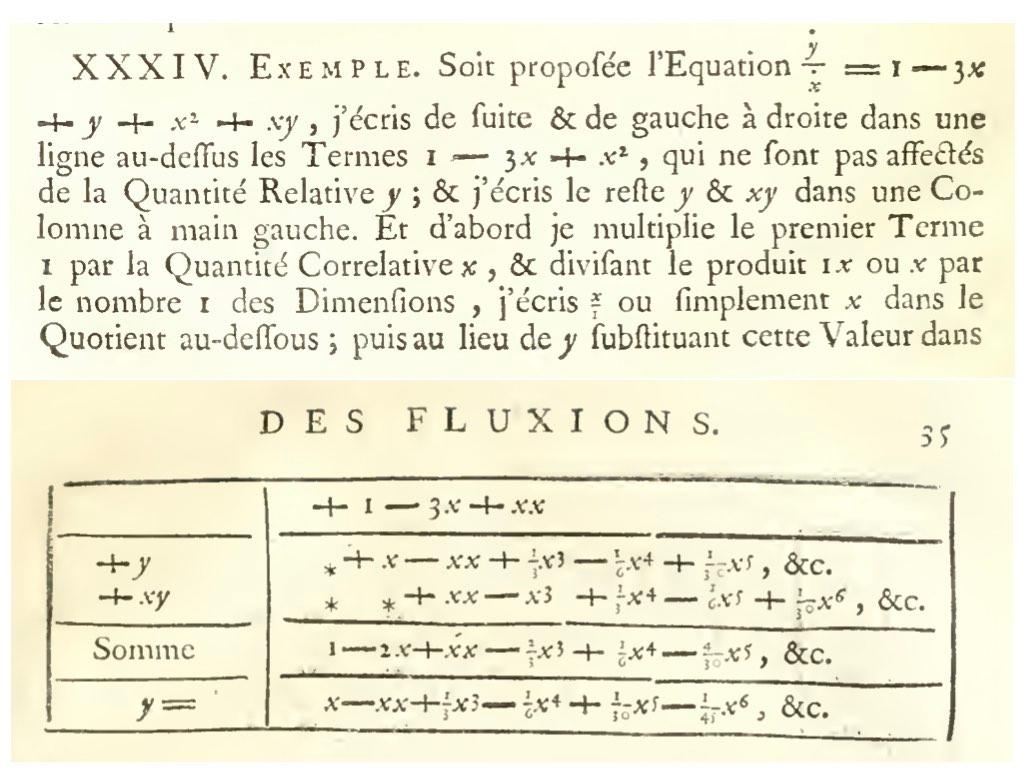

Image from Newton's Methodus Fluxionum et Serierum Infinitarum (1671).

One can find an analytical solution to this ODE by using the symbolic tool in Matlab (https://www.mathworks.com/help/symbolic/solve-a-single-differential-equation.html):

clear all
close
t=0:0.01:2;
t0=0;
C1=-exp((t0.*(t0 + 2))/2).*exp(- t0.^2/2 - t0).*(3*2^(1/2)*pi^(1/2)*erf(2^(1/2)*(0.5*t0 + 1/2)).*exp(0.5*t0.^2 + t0 + 1/2) - t0 + 4);
xtrue=@(t) C1*exp((t.*(t + 2))/2) + exp((t.*(t + 2))/2).*exp(-0.5* t.^2 - t).*(3*2^(1/2).*pi^(1/2).*erf(2^(1/2).*(0.5*t + 1/2)).*exp(t.^2/2 + t + 1/2) - t + 4);
plot(t,xtrue(t),'k-')
xlabel('t');
ylabel('x(t)');

**Part (a) (5 points)** In order to solve this ODE, Newton suggested an infinite series approach. His solution to the problem, with intial condition $x(0)=0$, was:


$$x(t)=\sum_{i=0}^{\infty}a_i t^{i}=a_0+a_1t+a_2t^2+...$$


where $a_0=0, a_1=1, a_2=-1, a_3=1/3, a_4=-1/6, \text{and for }4<n: a_n=(1/n)(a_{n-1}+a_{n-2}).$

Write a simple code that calculates this sum up to the first 100 terms. Plot your solution, xNewt, versus time and compare it with the exact analytical solution (xtrue).

% Place your code here
n=100;
a=[];
a(1) = 0;
a(2) = 1;
a(3) = -1;
a(4) = 1/3;
a(5) = -1/6;
for i = 6:n
    a(i) = (1/i)*(a(i-1)+a(i-2));
end
xNewt = zeros(1,n);
for t_index = 1:length(t)
    tval = t(t_index);
    sum = 0;
    for i = 1:n
        sum = sum + a(i)*tval^(i-1);
    end
    xNewt(t_index) = sum;
end

plot(t,xtrue(t),"g")
hold on
plot(t,xNewt,"b")

**Part (b) (5 points)** Solve the mentioned ODE with the Euler-Forward method in the $0\leq t\leq 2$ range. Use time steps dt=0.1s and dt=0.01s and plot both solutions on the same plot and compare them with the exact solution.

% Place your code here:
dt=0.1;
tnum=0:dt:2;
xnum=zeros(size(tnum));
xnum(1)=0;
dxdt=@(t,x) (1+t)*x + 1 - 3*t + t^2;
for i=1:length(tnum)-1 % Loop through all the times (except the last one)
    xnum(i+1)=xnum(i)+dxdt(tnum(i),xnum(i))*dt; % Apply the marching formula
end
figure
hold on
plot(tnum,xnum,'g-.')
dt2 = 0.01;
tnum2=0:dt2:2;
xnum2 = zeros(size(tnum2));
xnum2(1) = 0;
for i=1:length(tnum2)-1 % Loop through all the times (except the last one)
    xnum2(i+1)=xnum2(i)+dxdt(tnum2(i),xnum2(i))*dt2; % Apply the marching formula
end
plot(tnum2,xnum2,'b-.')
plot(tnum,xtrue(tnum),"r-")

**Part (c) (5 points)** Repeat the Euler-Forward scheme using 6 different values of time steps dt from dtvector=[1 0.1 0.01 0.001 0.0001 0.00001];. For each solution calculate the error by taking the difference between the numerical solution and the analtical one at $t=2$. Plot the calculated values of error versus 1/dt.

% Place your code here:
dtvector=[1 0.1 0.01 0.001 0.0001 0.00001];
errorvector = zeros(size(dtvector));
for i=1:length(dtvector)
    dt=dtvector(i);
    tnum = 0:dt:2;
    xnum = zeros(size(tnum));
    xnum(1) = 0;
    for j=1:length(tnum)-1 % Loop through all the times (except the last one)
        xnum(j+1)=xnum(j)+dxdt(tnum(j),xnum(j))*dt; % Apply the marching formula
    end
    errorvector(i)=abs(xtrue(2)-xnum(end));
end
figure
loglog(dtvector.^(-1),errorvector,'r-.')
xlabel('1/dt');
ylabel('error');

**Part (d) (2 points)** Based on the error plot in part (c), discuss what is the convergence order for the the Euler-Forward method.

hold on
plot(dtvector.^(-1),dtvector,"g.")
% Write your comments here: it is order one. Error ~ dt^1

**Part (e) (3 points)** Write a new code that solves the problem with both the Euler-Forward and the Euler-Backward methods. Repeat the procedure for 4 different values of time step dt (from dtvector=[1 0.1 0.01 0.001];) and do a tic-toc measurement of the computation time for both methods at each value of dt. 

Plot the computation time versus 1/dt for both methods. 

% Place your code here:
dtvector=[1 0.1 0.01 0.001];
timeEF=ones(size(dtvector));
timeEB=ones(size(dtvector));
figure
plot(t,xtrue(t),"r-")
hold on
for i=1:length(dtvector)
    dt = dtvector(i);
    tnum = 0:dt:2;
    EF = zeros(size(tnum));
    EF(1) = 0;
    EB = zeros(size(tnum));
    EB(1) = 0;
    %Euler-Forward
    tic
        for j=1:length(tnum)-1
            EF(j+1)=EF(j)+dxdt(tnum(j),EF(j))*dt; % Apply the marching formula
        end
    timeEF(i)=toc;
    
    %Euler-Backward
    tic
        for j=2:length(tnum)
            fz=@(x_new) x_new-(EB(j-1)+dxdt(tnum(j),x_new)*dt); % This will be zero when the marching formula is satisfied
            x_guess=EB(j-1); % Use the most recent value as an intial guess
            EB(j)=fzero(fz,x_guess); % Apply the marching formula
        end
    timeEB(i)=toc;
    plot(tnum,EF,".-")
    plot(tnum,EB,"--")
end
legend("true","dt=1 EF","dt=1 EB","dt=.1 EF","dt=.1 EB","dt=.01 EF","dt=.01 EB","dt=.001 EF","dt=.001 EB")
xlabel("t")
ylabel("x")
figure
loglog(dtvector.^(-1),timeEF)
hold on
loglog(dtvector.^(-1),timeEB)
xlabel('1/dt')
ylabel('computation time')
legend("EF","EB")


% provide simple comments about the relative difference in computation plot between the two methods.
% backward euler has a significantly larger time because the
% creation/storing of a new function and running fzero() takes time.

## Problem 2 Trajectory of Sport Balls (30 points)

The trjectory of a projectile such as a sport ball or a bullet is of interest in many different applications. In general, scientists have recorded two major trajectories. At relatively low launch velocities (compared to the terminal velocity) the object takes a parabolic trajectory (*e.g.* the trajectory of the basketball in the image below). However, at large launch velocities (compared to the terminal velocity) the object follows an asymmetric profile known as Tartaglia's curve (*e.g.* the trajectory of the shuttlecock in badminton). In this problem we aim to investigate these trajectories numerically.

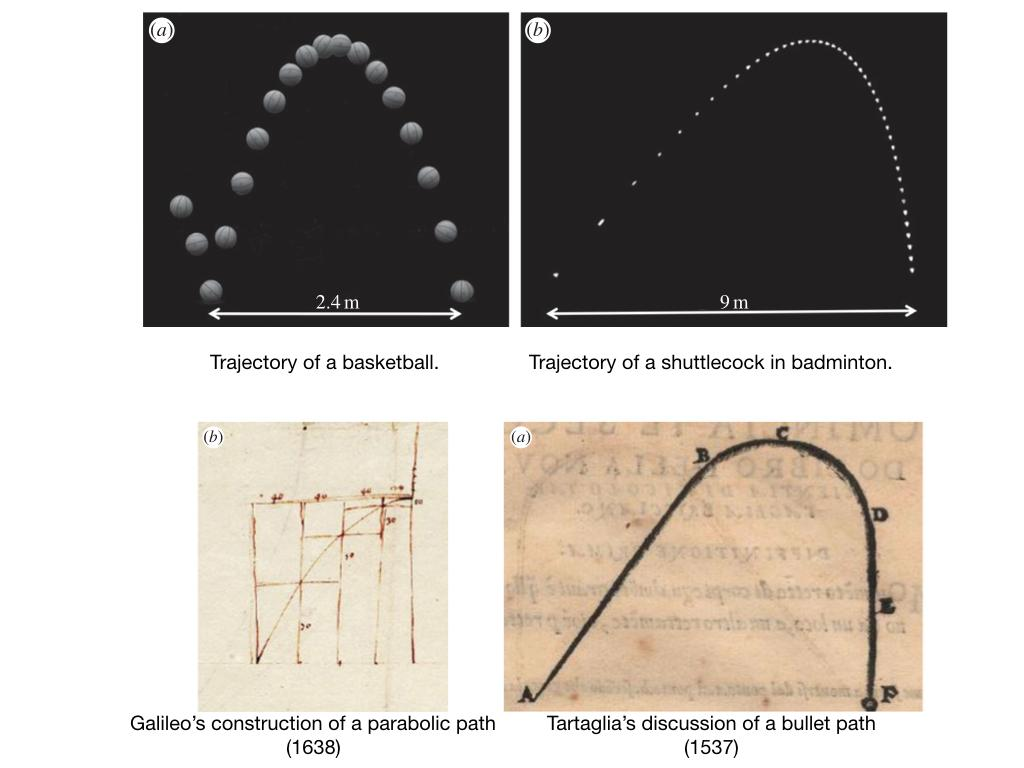

images taken from: Clanet, C., 2015. Sports ballistics. *Annual Review of Fluid Mechanics*, *47*, pp.455-478.

If the ball/object is not spinning, the overall acceleration of the objects is balanaced with the net sum of gravitational and aerodynamic drag forces and the equation of motion can be written in the following form:


$$M\frac{d\;\overrightarrow{\mathit{\mathbf{u}}} }{d\;t}=M\;\overrightarrow{\mathit{\mathbf{g}}} -\frac{1}{2}\rho C_D \;\pi \;R^2 \left|u\right|\overrightarrow{\mathit{\mathbf{u}}}$$


where $M$is the mass of object, $\overrightarrow{\mathit{\mathbf{u}}}$is the velocity vector, $\overrightarrow{\mathit{\mathbf{g}}}$is the gravity vector, $\rho$ is the density of air, $R$ is the effective/approximate radius of the object and $C_D$is the aerodynamic drag coefficient.

**Part (a) (5 points)** For a basketball shot, the following information is given to us:

%basketball
M=0.65; % in kg
g=[0;-9.8];% in m/s^2
rho=1.20; % kg/m^3
CD=0.24;
R=0.12; % m

We are also given that the ball has an initial velocity of u_0=15*[cos(theta_0);sin(theta_0)]; where theta_0=74 degrees. 

Write a simple code that finds a numerical solution for the mentioned ODE (for the velocity vector) in the $0\leq t\leq3$range with dt=0.040 s. Find the numarical solution based on both the Euler-Forward method u_ef and the midpoint method u_mp. Plot the temporal evolution of the two velocity components ($u_x(t),u_y(t)$) from the midpoint scheme.

% Place your code here:

theta_0=74*(pi/180);% in radians
u_0=15*[cos(theta_0);sin(theta_0)]; % in m/s
dudt=@(t,u) g - (1/2)*rho*CD*pi*(R^2)*sqrt(u(1,:)^2+u(2,:)^2)*u*(1/M);
dt = 0.040;
t = 0:dt:3;
u_ef = zeros(2,length(t));
u_ef(:,1) = u_0;
for i=1:length(t)-1 % Loop through all the times (except the last one)
    u_ef(:,i+1)=u_ef(:,i)+dudt(t(i),u_ef(:,i))*dt; % Apply the marching formula
end
u_mp = zeros(2,length(t));
u_mp(:,1) = u_0;
for i=1:length(t)-1 % Loop through all the times (except the last one)
    u_mp(:,i+1)=u_mp(:,i)+dudt(t(i)+dt/2,u_mp(:,i)+dudt(t(i),u_mp(:,i))*dt/2)*dt; % Apply the midpoint marching formula
end

figure
plot(t,u_mp(1,:),"r-")
hold on
plot(t,u_mp(2,:),"r--")
% plot(t,u_ef(1,:),"b-")
% plot(t,u_ef(2,:),"b--")
xlabel('t[s]')
ylabel('u_x and u_y')
legend("ux","uy")
% figure
% plot(u_ef(1,:),u_ef(2,:),"r")
% hold on
% plot(u_mp(1,:),u_mp(2,:),"b")


**Part (b) (5 points)** The basketball started its trajectory from $[x(0);y(0)]=[0;0]$. Use your solution for the velocity components from part (a) (from either the Euler-Forward method or the midpoint method) and perfom a numerical integration to find the trajectory of the bascetball [Xbasketball(t); Ybasketball(t)]. 

Hint: You can use trapz for integration and remeber that:

$x(t)=x(0)+\int_0^tu_x(s)ds$ and $y(t)=y(0)+\int_0^tu_y(s)ds$

% Place your code here:

Xbasketball=[];
Ybasketball=[];
Xbasketball(1)=0;
Ybasketball(1)=0;
% for i = 2:length(t)
%     Xbasketball(i) = Xbasketball(1) + trapz([0 t(i)],[u_ef(1,1) u_ef(1,i)]);
%     Ybasketball(i) = Ybasketball(1) + trapz([0 t(i)],[u_ef(2,1) u_ef(2,i)]);
% end
for i = 2:length(t)
    Xbasketball(i) = Xbasketball(1) + trapz(t(1:i),u_ef(1,1:i));
    Ybasketball(i) = Ybasketball(1) + trapz(t(1:i),u_ef(2,1:i));
end
figure
plot(Xbasketball,Ybasketball,'bo')
xlabel('x(t)[m]')
ylabel('y(t)[m]')

**Part (c) (5 points)** Repeat parts a and b for a badminton shuttlecock which was launched with an initial velocity u_0=40*[cos(theta_0);sin(theta_0)]; where theta_0=60 degrees. Solve the ODE for the velocity vector, find the trajectory and save it as [Xshuttlecock(t); Yshuttlecock(t)]. Plot the trajectory.

%%%%%%% badminton shuttlecock
theta_0=60*(pi/180);% in radians
u_0=40*[cos(theta_0);sin(theta_0)]; % in m/s
M=0.005; % in kg
g=[0;-9.8];% in m/s^2
rho=1.20; % kg/m^3
CD=0.60;
R=0.03; % m

% F = @(t,u) M*g - (1/2)*rho*CD*pi*(R^2)*sqrt(u(1,:)^2+u(2,:)^2)*u;
dudt=@(t,u) g - (1/2)*rho*CD*pi*(R^2)*sqrt(u(1,:)^2+u(2,:)^2)*u*(1/M);
[tout, u_mp] = ode45(dudt,t,u_0);
u_mp = u_mp';
tout = tout';

figure
plot(tout,u_mp(1,:),"r-")
hold on
plot(tout,u_mp(2,:),"b-")

xlabel('t[s]')
ylabel('u_x and u_y')
legend("ux","uy")
Xshuttlecock=[];
Yshuttlecock=[];
Xshuttlecock(1)=0;
Yshuttlecock(1)=0;

for i = 2:length(t)
    Xshuttlecock(i) = Xshuttlecock(1) + trapz(t(1:i),u_mp(1,1:i));
    Yshuttlecock(i) = Yshuttlecock(1) + trapz(t(1:i),u_mp(2,1:i));
end

% Xshuttlecock2=[];
% Yshuttlecock2=[];
% Xshuttlecock2(1)=0;
% Yshuttlecock2(1)=0;
% for i = 2:length(tout)
%     Xshuttlecock2(i) = Xshuttlecock2(1) + trapz([0 tout(i)],[u_mp2(1,1) u_mp2(1,i)]);
%     Yshuttlecock2(i) = Yshuttlecock2(1) + trapz([0 tout(i)],[u_mp2(2,1) u_mp2(2,i)]);
% end

figure
plot(Xshuttlecock,Yshuttlecock,'bo')
hold on
%plot(Xshuttlecock2,Yshuttlecock2,'ro')
xlabel('x(t)[m]')
ylabel('y(t)[m]')

**Part (d) (2 Points)** Which tajectory is closer to the parabolic profile ? and which one is closer to the Tartaglia's curve ?

% place your comments here:
% Basketball is more parabolic and shuttlecock is more Tartaglia-ic.

**Part (e) (8 points)** The studied ODE has an exact solution when g=[0;0]. The utrue function (below) provides you with the exact solution for the velocity vector when g=[0;0].

Solve the ODE for the g=[0;0] case numerically by both the Euler-Forward and midpoint schemes in the $0\leq t\leq3$ range with five different values of time step dt (dtvector=[0.1 0.01 0.001 0.0001 0.00001];). Use the exact solution to calculate the error in both Euler-forward and midpoint methods at $t=3$ for all five values of dt. Plot the error versus 1/dt and comment on the order of convergence for these two methods.

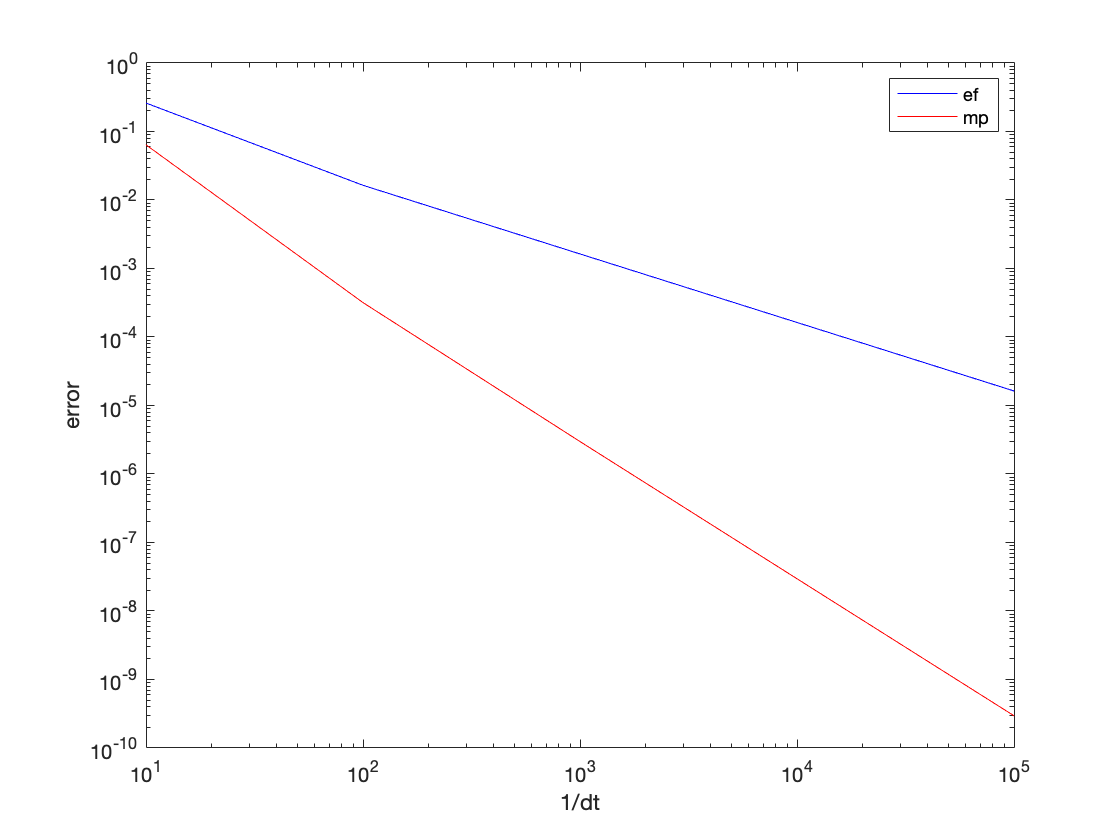

% Place your code here:
%%%%%% badminton shuttlecock
theta_0=60*(pi/180);% in radians
u_0=40*[cos(theta_0);sin(theta_0)]; % in m/s
M=0.005; % in kg
g=[0;0];% in m/s^2
rho=1.20; % kg/m^3
CD=0.60;
R=0.03; % m
utrue=@(t) [cos(theta_0)*((1/norm(u_0))+0.5*rho*pi*R^2*(CD/M)*t).^(-1);sin(theta_0)*((1/norm(u_0))+0.5*rho*pi*R^2*(CD/M)*t).^(-1)];

dudt=@(t,u) g - (1/2)*rho*CD*pi*(R^2)*sqrt(u(1,:)^2+u(2,:)^2)*u*(1/M);
dtvector=[0.1 0.01 0.001 0.0001 0.00001];
errorvector_mp=[];
errorvector_ef=[];
for i=1:length(dtvector)
    dt=dtvector(i);
    t = 0:dt:3;
    u_ef = zeros(2,length(t));
    u_ef(:,1) = u_0;
    u_mp = zeros(2,length(t));
    u_mp(:,1) = u_0;
    for j=1:length(t)-1 % Loop through all the times (except the last one)
        u_ef(:,j+1)=u_ef(:,j)+dudt(t(j),u_ef(:,j))*dt; % Apply the marching formula
        u_mp(:,j+1)=u_mp(:,j)+dudt(t(j)+dt/2,u_mp(:,j)+dudt(t(j),u_mp(:,j))*dt/2)*dt;% Apply the midpoint marching formula
    end
    errorvector_ef(i)=norm(utrue(t(end))-u_ef(:,end));
    errorvector_mp(i)=norm(utrue(t(end))-u_mp(:,end));
end
figure
loglog(dtvector.^(-1),errorvector_ef,'b-')
hold on
loglog(dtvector.^(-1),errorvector_mp,'r-')
xlabel('1/dt')
ylabel('error')
legend("ef","mp")

% Place your comments on solution convergence here:
% the order of convergence for Euler-Forward is order 1
% the order of convergence for midpoint method is order 3

a =     3.0000
    4.0000
   -3.0536
   -4.0715


**Part (f) (5 points)** In this part we want to find the range of a projectile $x_{range}$. As shown in the image, the range of a projectile is the horizontal distance the object travels before returining to the ground.

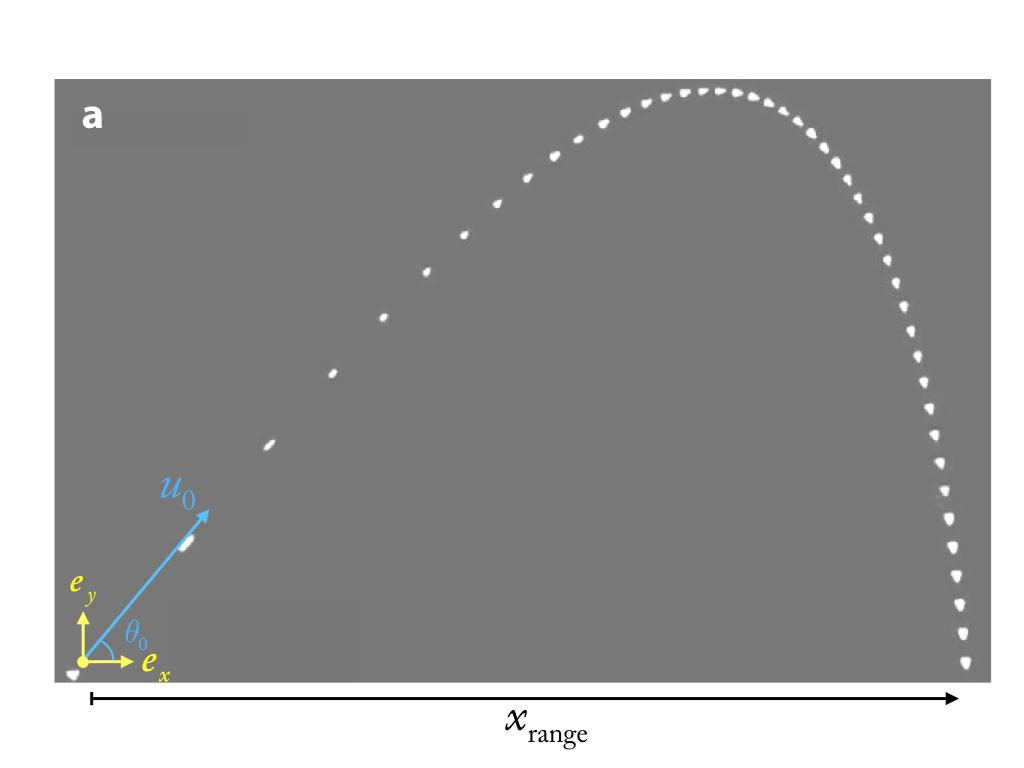

For a fixed magnitude of the initial velocity ($\left|u_0 \right|$), the range can change as we change the launch angle $0\leq \theta_0\leq \pi/2$. In different sports, athletes find the optimum angle to maximize the range. Using our ODE solution, we want to find the values of maximum range for different sports:

It is easier to use the ode45 solver to find the trajecotry of the ball directly. Assume that xu=[x(t);y(t);u_x(t);u_y(t)]. Define the correct function handle dxudt and solve the ODE using the ode45 command in the $0\leq t\leq 100$ range. For a fixed magnitude of the initial velocity vector (given to you for each specifc sport), change the launch angle theta_0 between 0 and 90 degrees (thetavector=linspace(0,90)) and find the maximum obtainable range (xrange).

%%%%%%%%%%%  Badminton   %%%%%%%%%%%%%%%%%%%
% Place your code for Badminton here :

thetavector=linspace(0,90);
xrange = zeros(size(thetavector));
for i=1:length(thetavector)
    theta_0=thetavector(i)*(pi/180);% in radians
    xu_0=[0;0;137*cos(theta_0);137*sin(theta_0)]; % in m/s
    M=0.005; % in kg
    g=[0;-9.8];% in m/s^2
    rho=1.20; % kg/m^3
    CD=0.60;
    R=0.03; % in m
    dxudt=@(t,xu) [xu(3,:); xu(4,:); g - (1/2)*rho*CD*pi*(R^2)*sqrt(xu(3,:)^2+xu(4,:)^2)*xu(3:4,:)*(1/M)];
    [tout xu] = ode45(dxudt,t,xu_0);
    xrange(i)=abs(xu(1,1)-xu(end,1));
end
xrange_badminton=max(xrange);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%% Handball %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Place your code for Handball here :

thetavector=linspace(0,90);
xrange = zeros(size(thetavector));
for i=1:length(thetavector)
    theta_0=thetavector(i)*(pi/180);% in radians
    xu_0=27*[0;0;cos(theta_0);sin(theta_0)]; % in m/s
    M=0.450; % in kg
    g=[0;-9.8];% in m/s^2
    rho=1.20; % kg/m^3
    CD=0.20;
    R=0.5*0.19; % m
    dxudt=@(t,xu) [xu(3,:); xu(4,:); g - (1/2)*rho*CD*pi*(R^2)*sqrt(xu(3,:)^2+xu(4,:)^2)*xu(3:4,:)*(1/M)];
    [tout xu] = ode45(dxudt,t,xu_0);
    xrange(i)=abs(xu(1,1)-xu(end,1));
end
xrange_Handball=max(xrange);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%% Baseball %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Place your code for Baseball here :

thetavector=linspace(0,90);
xrange = zeros(size(thetavector));
for i=1:length(thetavector)
    theta_0=thetavector(i)*(pi/180);% in radians
    xu_0=54*[0;0;cos(theta_0);sin(theta_0)]; % in m/s
    M=0.145; % in kg
    g=[0;-9.8];% in m/s^2
    rho=1.20; % kg/m^3
    CD=0.38;
    R=0.5*0.07; % m
    dxudt=@(t,xu) [xu(3,:); xu(4,:); g - (1/2)*rho*CD*pi*(R^2)*sqrt(xu(3,:)^2+xu(4,:)^2)*xu(3:4,:)*(1/M)];
    [tout xu] = ode45(dxudt,t,xu_0);
    xrange(i)=abs(xu(1,1)-xu(end,1));
end
xrange_baseball=max(xrange);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%% Golf %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Place your code for Golf here :

thetavector=linspace(0,90);
xrange = zeros(size(thetavector));
for i=1:length(thetavector)
    theta_0=thetavector(i)*(pi/180);% in radians
    xu_0=91*[0;0;cos(theta_0);sin(theta_0)]; % in m/s
    M=0.045; % in kg
    g=[0;-9.8];% in m/s^2
    rho=1.20; % kg/m^3
    CD=0.23;
    R=0.5*0.042; % m
    dxudt=@(t,xu) [xu(3,:); xu(4,:); g - (1/2)*rho*CD*pi*(R^2)*sqrt(xu(3,:)^2+xu(4,:)^2)*xu(3:4,:)*(1/M)];
    [tout xu] = ode45(dxudt,t,xu_0);
    xrange(i)=abs(xu(1,1)-xu(end,1));
end
xrange_golf=max(xrange);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Your friend claims that different sports have evolved in a way that the field size scales with the corresponding maximum range for the sport ball. Below are the typical values of field length for badminton, handball, baseball and golf.

Lfield_Badminton=13.4; % in m
Lfield_Handball=40; % in m
Lfield_Baseball=110;% in m
Lfield_Golf=225;% in m

Provid a plot of field length versus maximum range. Is your friend correct ? do you see a correlation ?

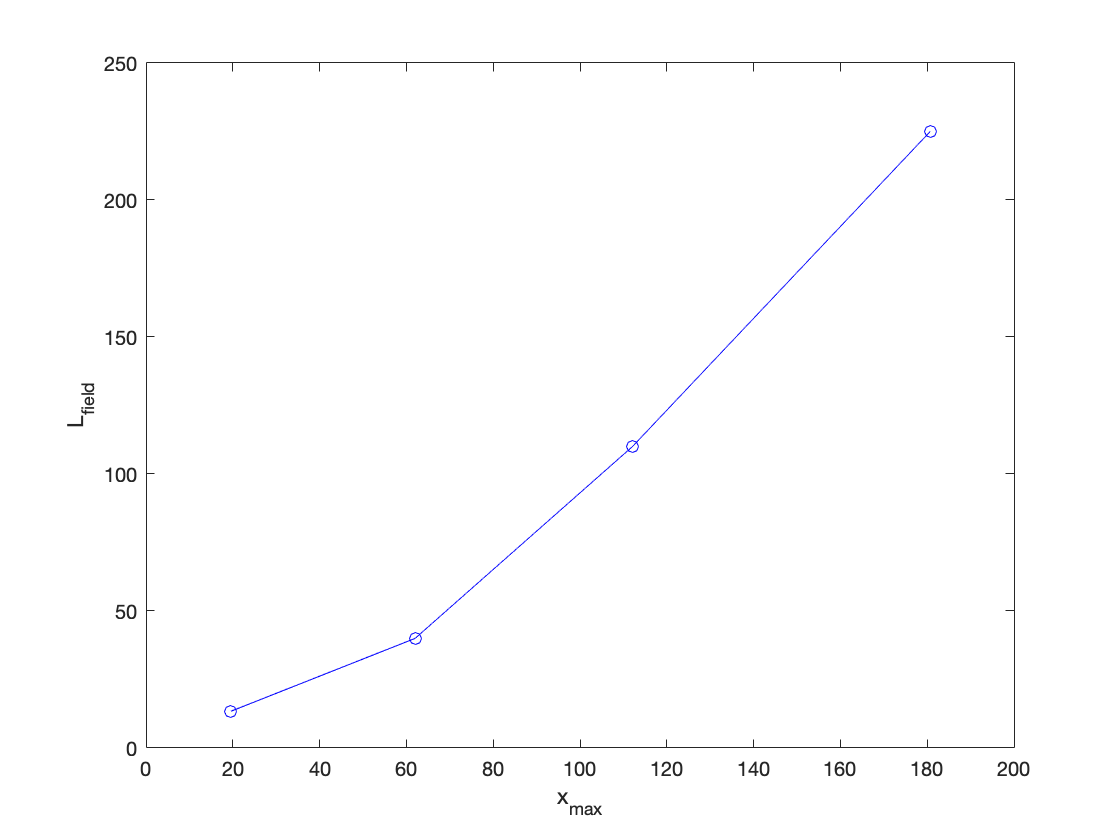

xrangeAll=[xrange_badminton xrange_Handball xrange_baseball xrange_golf];
LfieldAll=[Lfield_Badminton Lfield_Handball Lfield_Baseball Lfield_Golf];
figure
plot(xrangeAll,LfieldAll,'bo-')
xlabel('x_{max}')
ylabel('L_{field}')

%yes, I see a correlation

For comparison you can do this for many different sports:

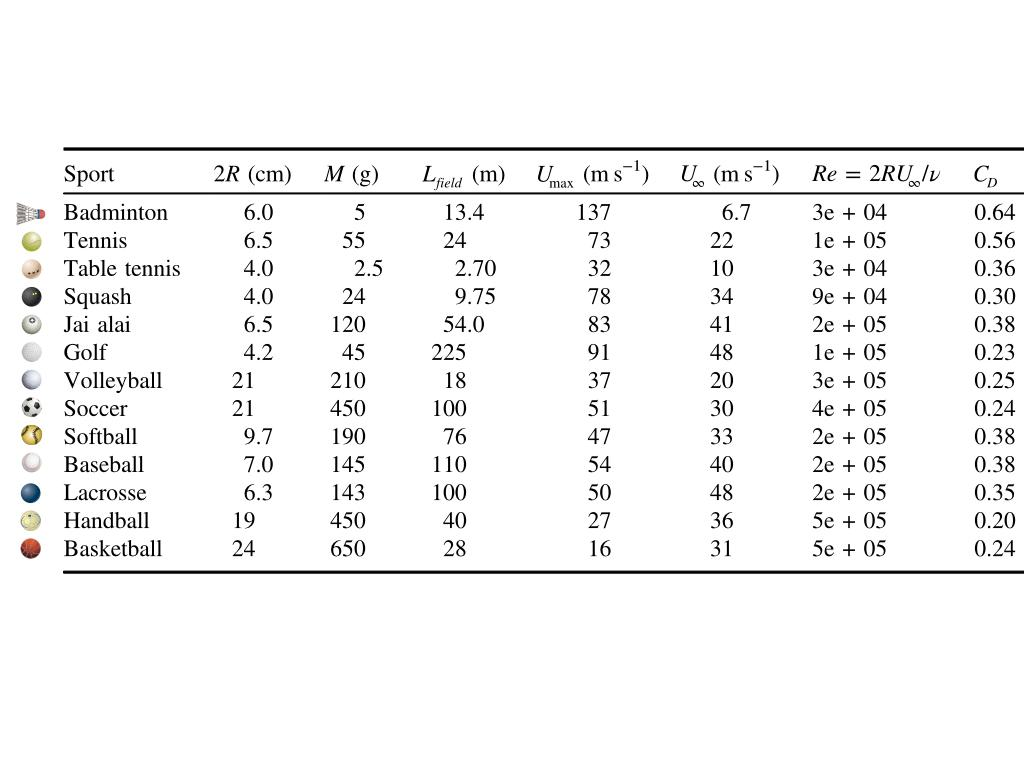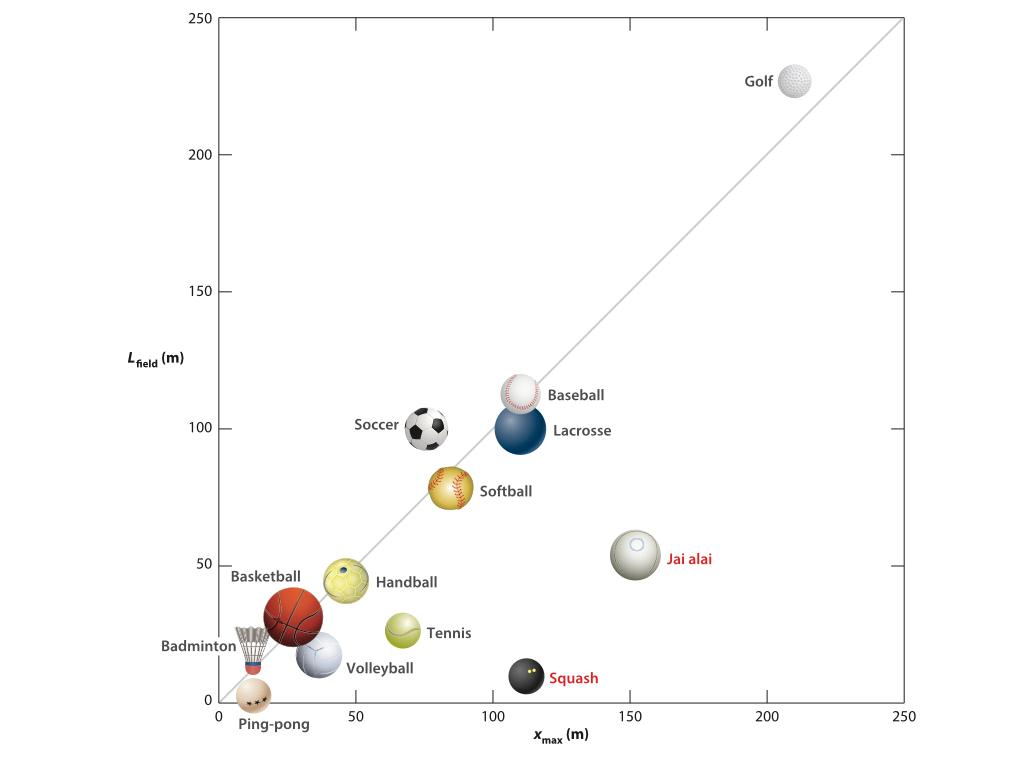

Image and table taken from: Clanet, C., 2015. Sports ballistics. *Annual Review of Fluid Mechanics*, *47*, pp.455-478.

## Problem 3 The paradoxial pop-ups (20 points)

A pop-up in baseball is a batted ball hit very high that stays in the infield. Usually these balls are very easy to catch, and thus the batter is out. However, with large slice, these balls become very difficult to catch, even for major league infielders (Figure below).

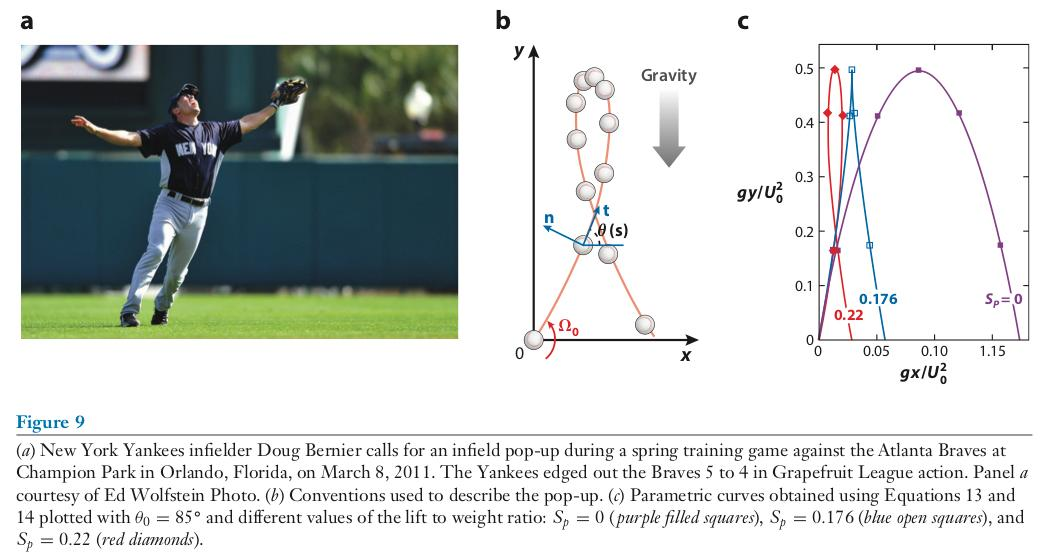

image taken from: Clanet, C., 2015. Sports ballistics. *Annual Review of Fluid Mechanics*, *47*, pp.455-478.

This phenomenon happens due to the spin effect of the ball. Spinning balls can generate inward lift force in their trajectory (the so-called Magnus effect in aerodynamics, for more information you can watch this fun video: [https://www.youtube.com/watch?v=2OSrvzNW9FE](https://www.youtube.com/watch?v=2OSrvzNW9FE) ).

If the ball/object is spinning, the overall acceleration of the objects is balanaced with the net sum of gravitational and aerodynamic drag and lift forces and the equation of motion can be written in the following form:


$$M\frac{d\;\overrightarrow{\mathit{\mathbf{u}}} }{d\;t}=M\;\overrightarrow{\mathit{\mathbf{g}}} -\frac{1}{2}\rho C_D \;\pi \;R^2 \left|u\right|\overrightarrow{\mathit{\mathbf{u}}} +C_{\Omega } \rho R^3 \Omega^{\to } \times \overrightarrow{\mathit{\mathbf{u}}}$$


where $M$is the mass of object, $\overrightarrow{\mathit{\mathbf{u}}} =\left\lbrack u_x ;u_y ;0\right\rbrack$is the velocity vector, $\Omega^{\to } =\left\lbrack 0;0;\Omega_0 \right\rbrack$is the spin vector of the ball, $\overrightarrow{\mathit{\mathbf{g}}} =\left\lbrack 0;-9\ldotp 81;0\right\rbrack$is the gravity vector, $\rho$ is the density of air,$R$ is the effective/approximate radius of the object, $C_D$is the aerodynamic drag coefficient and $C_\Omega$is the spin coefficient. A relevant dimensionless ratio for this problem is the $Sp\equiv\frac{\rho R^3\Omega_0 U_0C_\Omega}{Mg}$ group which captures the strength of the spin-generated lift compared to the weight of the object.

**Part (a) (10 points)** We aim to study the trajectory of a baseball in a pop-up scenario. Write a code that solves the governing equation for the velocity vector using the Euler-backward method in the $0\leq t\leq 9$ range with time step dt=0.1. Hint: in this implicit solver, fsolve can be a useful substitution for fzero.

%%%%%%% Baseball %%%%%%%%

% Place your code for Baseball here :

theta_0=85*(pi/180);% in radians;

u_0=54*[cos(theta_0);sin(theta_0);0]; % in m/s
M=0.145; % in kg
g=[0;-9.8;0];% in m/s^2
rho=1.20; % kg/m^3
CD=0.38;
COmega=1.7;
R=0.5*0.07; % m
Omega_0_b=[0;0;0];

dudt=@(t,u) g - (1/2)*rho*CD*pi*(R^2)*norm(u)*u*(1/M) + COmega*rho*(R^3)*cross(Omega_0_b,u)*(1/M);
dt=0.1;
tnum=0:dt:9;
unum=zeros(3,length(tnum));
unum(:,1)=u_0;

for j=2:length(tnum)
    fz=@(u_new) u_new-(unum(:,j-1)+dudt(tnum(j),u_new)*dt); % This will be zero when the marching formula is satisfied
    u_guess=unum(:,j-1); % Use the most recent value as an intial guess
    unum(:,j)=fsolve(fz,u_guess); % Apply the marching formula
end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

**Part (b) (10 points)** Find the velocity of the baseball for two cases: 1) No spinning *i.e.*Omega_0_a=[0;0;0];  2) Spinning *i.e. *Omega_0_a=[0;0;600];.

Integrate the veloicty to find the trajectory of the baseball with time (use the trapz command). Plot the corresponding trajectories on the same fugure (blue circles for no spinning and red circles for spinning).

Omega_0_a=[0;0;600];
Omega_0_b=[0;0;0];
dudt_a=@(t,u) g - (1/2)*rho*CD*pi*(R^2)*norm(u)*u*(1/M) + COmega*rho*(R^3)*cross(Omega_0_a,u)*(1/M);
dudt_b=@(t,u) g - (1/2)*rho*CD*pi*(R^2)*norm(u)*u*(1/M) + COmega*rho*(R^3)*cross(Omega_0_b,u)*(1/M);
dt=0.1;
tnum=0:dt:9;
unum_a=zeros(3,length(tnum));
unum_a(:,1)=u_0;
unum_b=zeros(3,length(tnum));
unum_b(:,1)=u_0;

for j=2:length(tnum)
    fa=@(u_new) u_new-(unum_a(:,j-1)+dudt_a(tnum(j),u_new)*dt); % This will be zero when the marching formula is satisfied
    u_guess=unum_a(:,j-1); % Use the most recent value as an intial guess
    unum_a(:,j)=fsolve(fa,u_guess); % Apply the marching formula
    fb=@(u_new) u_new-(unum_b(:,j-1)+dudt_b(tnum(j),u_new)*dt); % This will be zero when the marching formula is satisfied
    u_guess=unum_b(:,j-1); % Use the most recent value as an intial guess
    unum_b(:,j)=fsolve(fb,u_guess); % Apply the marching formula
end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


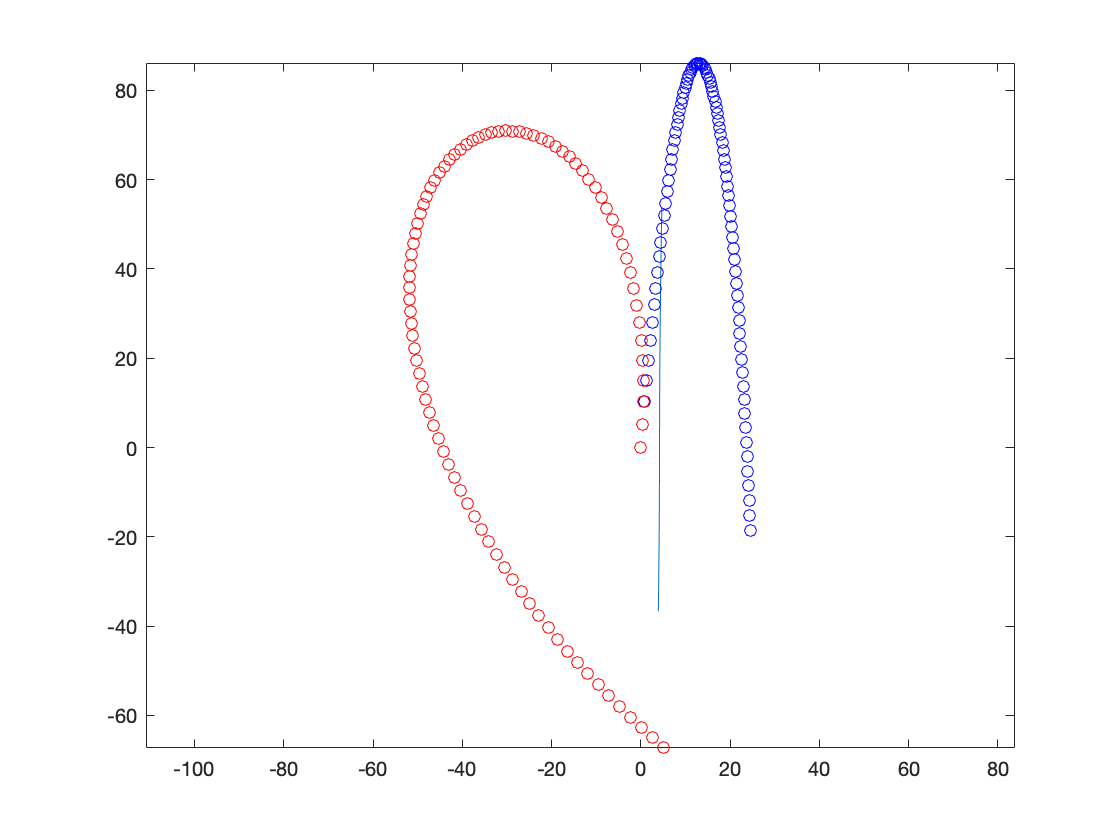


XbaseballzeroOmega=[];
YbaseballzeroOmega=[];
XbaseballzeroOmega(1)=0;
YbaseballzeroOmega(1)=0;
for i = 2:length(tnum)
    XbaseballzeroOmega(i) = XbaseballzeroOmega(1) + trapz(tnum(1:i),unum_b(1,1:i));
    YbaseballzeroOmega(i) = YbaseballzeroOmega(1) + trapz(tnum(1:i),unum_b(2,1:i));
end
XbaseballnonzeroOmega=[];
YbaseballnonzeroOmega=[];
XbaseballnonzeroOmega(1)=0;
YbaseballnonzeroOmega(1)=0;
for i = 2:length(tnum)
    XbaseballnonzeroOmega(i) = XbaseballnonzeroOmega(1) + trapz(tnum(1:i),unum_a(1,1:i));
    YbaseballnonzeroOmega(i) = YbaseballnonzeroOmega(1) + trapz(tnum(1:i),unum_a(2,1:i));
end
hold on
plot(XbaseballzeroOmega,YbaseballzeroOmega,'bo')
plot(XbaseballnonzeroOmega,YbaseballnonzeroOmega,'ro')
axis('equal')

## **Problem 4** **The chaotic situation for Euler-forward (15 points)**

We aim to solve the following ODE:

 
$$\frac{dx}{dt}=t-x^2;\:\:\:\text{Initial Condition:}\:x(0)=0$$


**Part (a) (6 points)** Solve the equation numerically by using the Euler-forward algorithm and find the solution in the $0\leq t\leq 900$range with time step dt=0.05. Plot your solution $x(t)$.

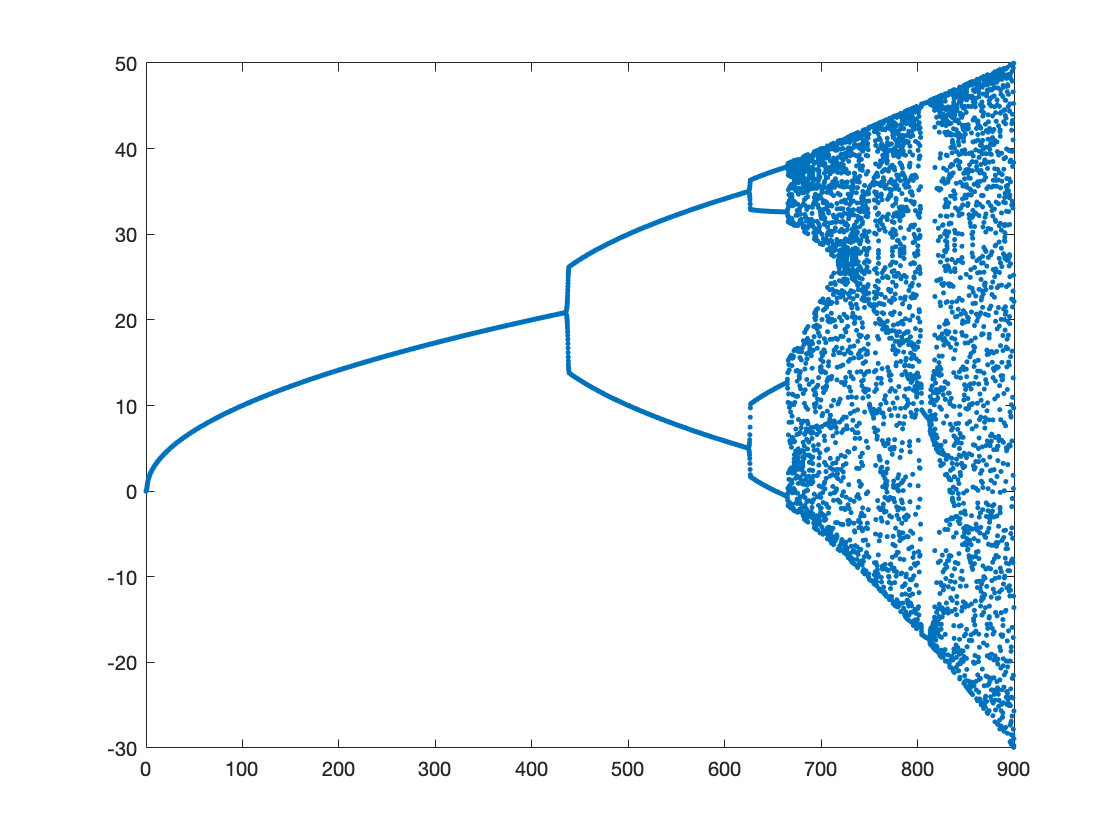

% place your code here:
dt=0.05;
t=0:dt:900;
x=zeros(size(t));
x(1) = 0;
dxdt = @(t,x) t-(x^2);
for i=1:length(t)-1 % Loop through all the times (except the last one)
    x(i+1)=x(i)+dxdt(t(i),x(i))*dt; % Apply the marching formula
end
figure
plot(t,x,'.')

Do you trust the solution ? Explain why.

% place your comments here: no, it doesn't look like a function; the
% branches do not describe the behavior of the ODE


**Part (b)** **(6 points)** Wrie a new code to solve the equation using the Crank-Nicolson algorithm and find the numerical solution in the $0\leq t\leq 900$ range with dt=0.05. Plot your solution $x(t)$.

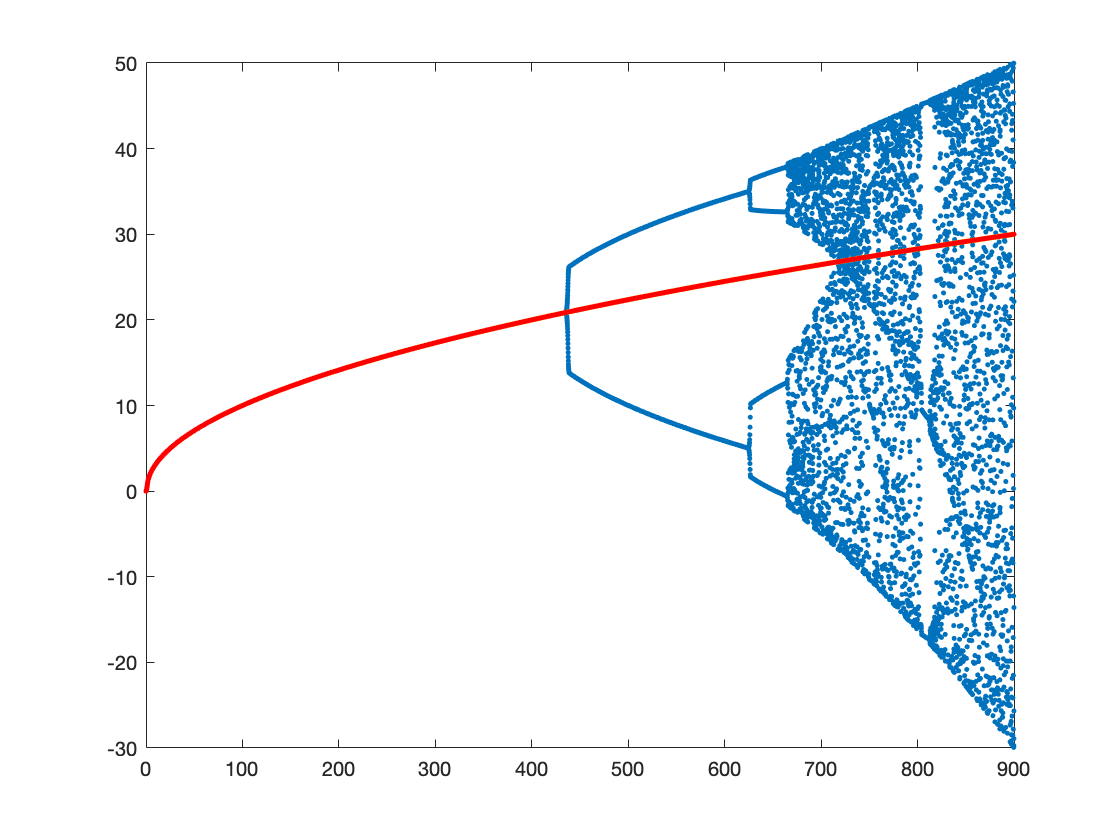

% place your code here:

dt=0.05;
t=0:dt:900;
x=zeros(size(t));
x(1) = 0;
for j=1:length(t)-1 % Loop through all the times (except the first one)
    fz = @(xnew) xnew-x(j)-(dt/2)*dxdt(t(j),x(j))-(dt/2)*dxdt(t(j+1),xnew);
    x(j+1) = fzero(fz,x(j));
end
hold on
plot(t,x,'.')

Do you trust the solution ? Explain why.

% place your comments here:
% yes, the plot looks like a second order ODE. Furthermore, the
% crank-nicolson algorithm has an error order of 2

**Part (c) (3points)** Write a simple code to solve the ODE with the ode45 command. Add your solution to previous plots.

% place your code here:
[tout x] = ode45(dxdt,t,x(1));
plot(t,x,'.')
legend("")

## Problem 5 Lissajous or Bowditch curves (15 points)

You have probably noticed the interesting curves that are inside the logo of the MIT Lincoln Laboratories. These curves/orbits are called Lissajous or Bowditch curves.

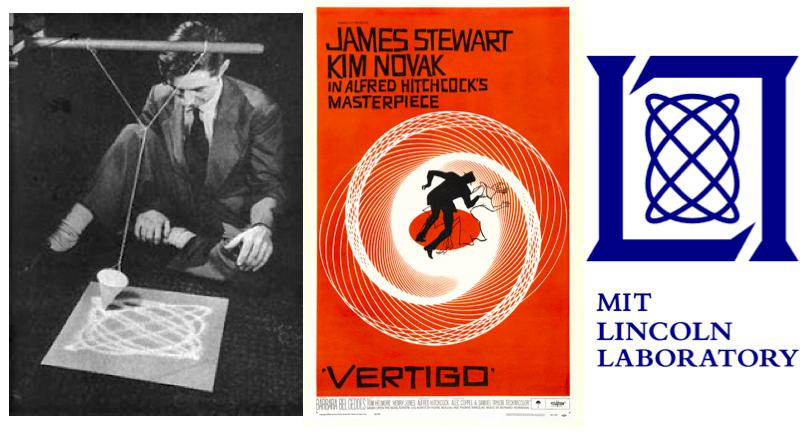

images taken from Wikimedia

Many artists includeing Max Ernst (left) and Alfred Hitchcock in Vertigo (middle) generated visual effects with Lissajous or Bowditch curves. These curved were generated by a mechanical device known as the "Harmonograph" ( [https://en.wikipedia.org/wiki/Harmonograph](https://en.wikipedia.org/wiki/Harmonograph) ) which is a pendulum with two degrees of freedom.

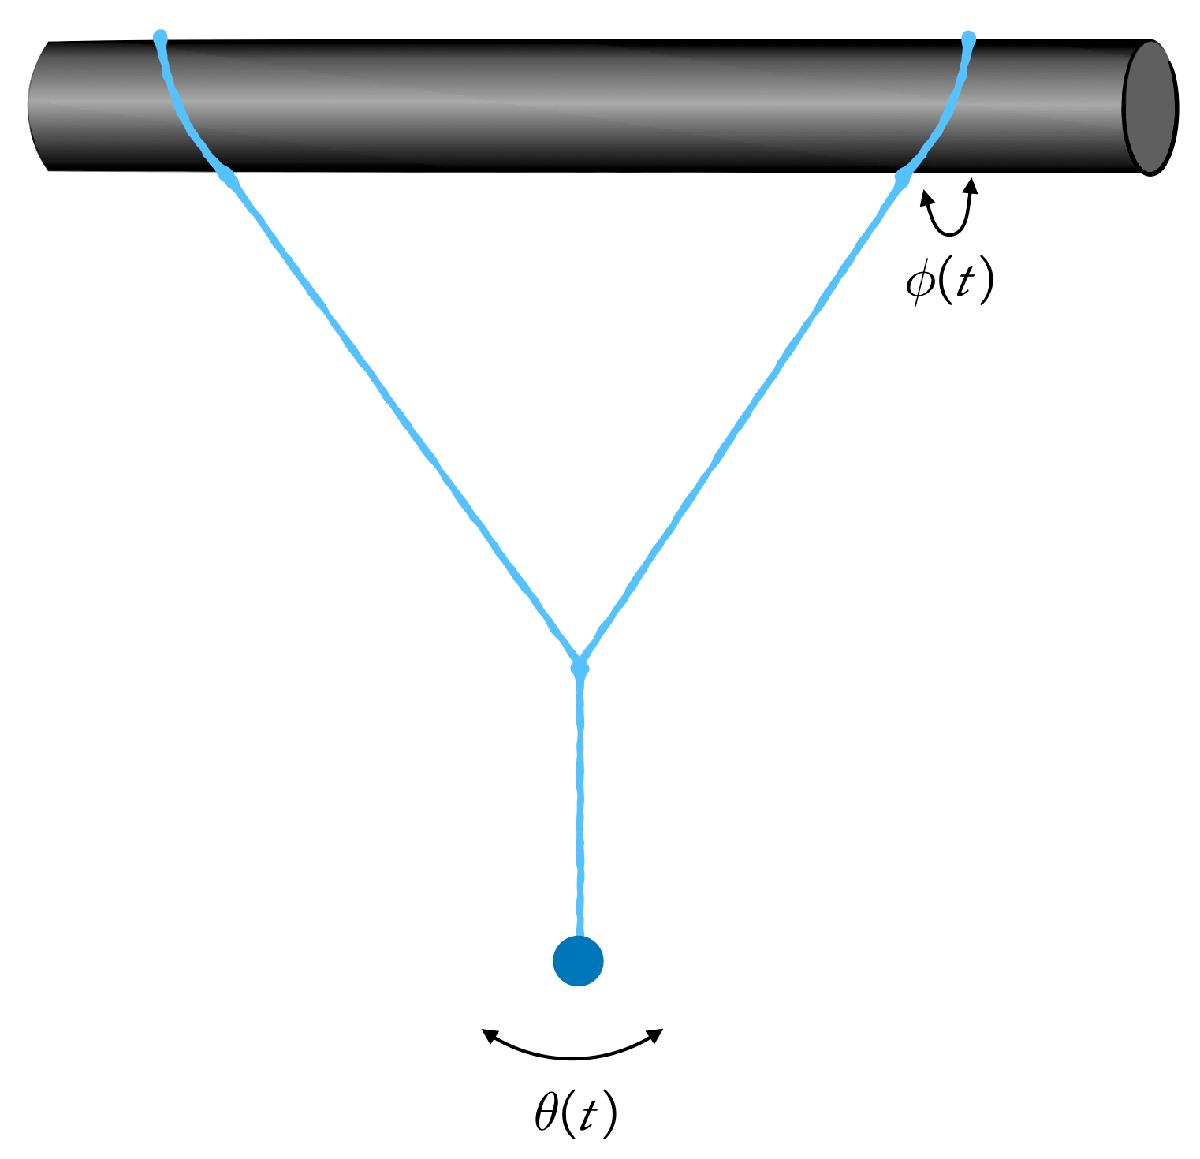

The equation of motion for the hanging mass (pen/paper in the Harmonograph) can be linearized into the following form which is known as damped harmonic oscillator:


$$\frac{d^2\theta}{dt^2}+\eta_\theta\frac{d\theta}{dt}+k_\theta\theta=0$$



$$\frac{d^2\phi}{dt^2}+\eta_\phi\frac{d\phi}{dt}+k_\phi\phi=0$$


**Part (a) (2 points)** For a given pendulum we have the following constants:

ktheta=1;
kphi=5;
mutheta=0.02;
muphi=0.04;

If thetaphi=$[\theta(t);\phi(t);d\theta/dt;d\phi/dt]$, find the matrix A, which can be used to express the temporal derivative of thetaphi in the following linear form:

d(thetaphi)/dt=  A * thetaphi; 

%place your code here:
A = [0, 0, 1, 0;
    0, 0, 0, 1;
    -ktheta, 0, -mutheta, 0;
    0, -kphi, 0, -mutheta;];

**Part (b) (5 points)** To find exact analytical solutions for this problem, we can use the eigenvectors and eigenvalues of the A matrix. As shown in the class (watch the "Stiff Systems" video), the exact solution is:

%place your code here:
thetaphi_0=[pi/6;pi/6;0;0];%% Initial conditions
[V D]=eig(A);
KS=[V(:,1).*exp(D(1,1)*0) V(:,2).*exp(D(2,2)*0) V(:,3).*exp(D(3,3)*0) V(:,4).*exp(D(4,4)*0)]\thetaphi_0;
utrue=@(t) KS(1)*V(:,1).*exp(D(1,1)*t)+KS(2)*V(:,2).*exp(D(2,2)*t)+KS(3)*V(:,3).*exp(D(3,3)*t)+KS(4)*V(:,4).*exp(D(4,4)*t);
dt=0.01;
t=0:dt:20;
X=utrue(t);
figure
plot(t,X(1,:))

xlabel('t[s]')
ylabel('\theta(t)')

Write a code based on the Euler-forward method that finds solutions for thetaphi(t) in the $0\leq t\leq 20$ range. Try your code for four different values of dt (dtvector=[1 0.1 0.01 0.001];). Plot the results for $\theta(t)$vs. $t$ and compare them with the exact solution.

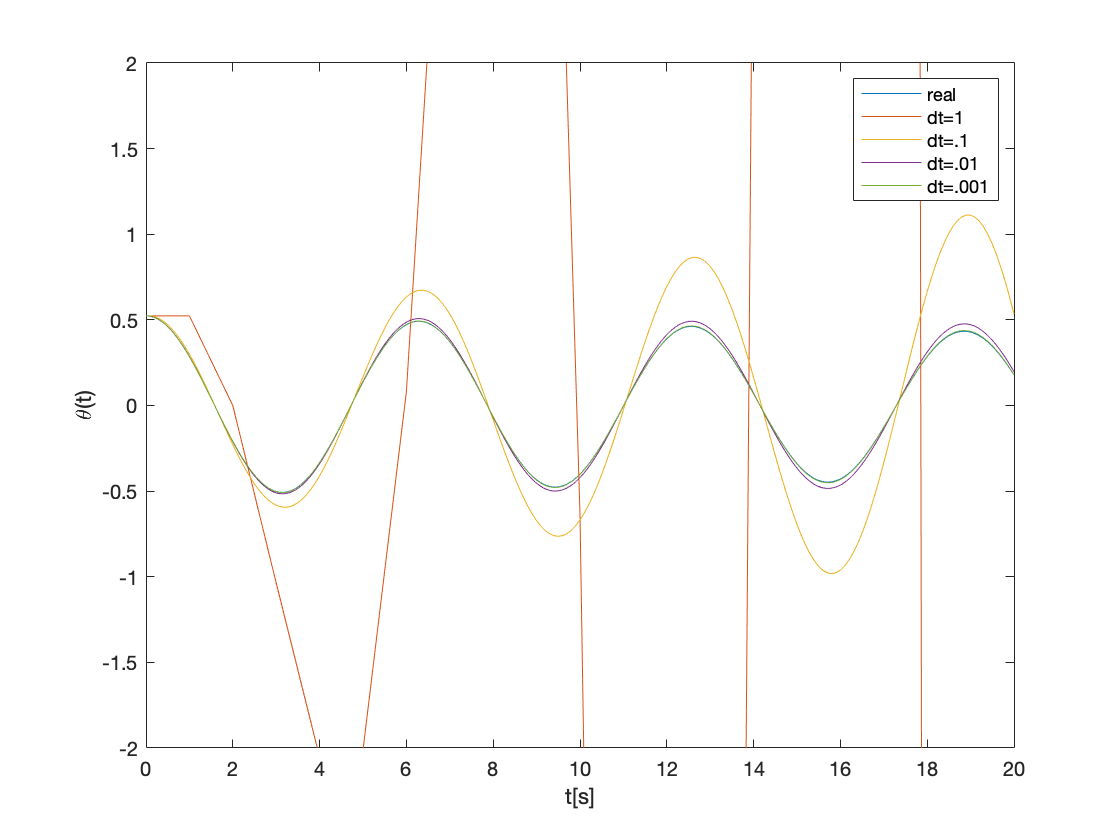

%place your code here:

dtvector=[1 0.1 0.01 0.001];
hold on
dthetaphidt = @(t,thetaphi) A*thetaphi;
for i=1:length(dtvector)
    dt = dtvector(i);
    t = 0:dt:20;
    thetaphi = zeros(4,length(t));
    thetaphi(:,1) = thetaphi_0;
    for j=1:length(t)-1 % Loop through all the times (except the last one)
        thetaphi(:,j+1)=thetaphi(:,j)+dthetaphidt(t(j),thetaphi(:,j))*dt; % Apply the marching formula
    end
    plot(t,thetaphi(1,:))
    ylim([-2 2])
end
legend("real","dt=1","dt=.1","dt=.01","dt=.001")

Which values of dt give rise to stable solutions ?

% place your answer here 
% all dt<1


**Part (c) (5 points)** Write a code that solves the ODE using the Euler-Backward method in the $0\leq t\leq 20$ range with dt=0.01;

%place your code here:

dtvector=0.01;
dt=dtvector;
t=0:dt:20;
thetaphi = zeros(4,length(t));
thetaphi(:,1) = thetaphi_0;
for j=2:length(t)
    fz=@(thetaphi_new) thetaphi_new-(thetaphi(:,j-1)+dthetaphidt(t(j),thetaphi_new)*dt); % This will be zero when the marching formula is satisfied
    thetaphi_guess=thetaphi(:,j-1); % Use the most recent value as an intial guess
    thetaphi(:,j)=fsolve(fz,thetaphi_guess); % Apply the marching formula
end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

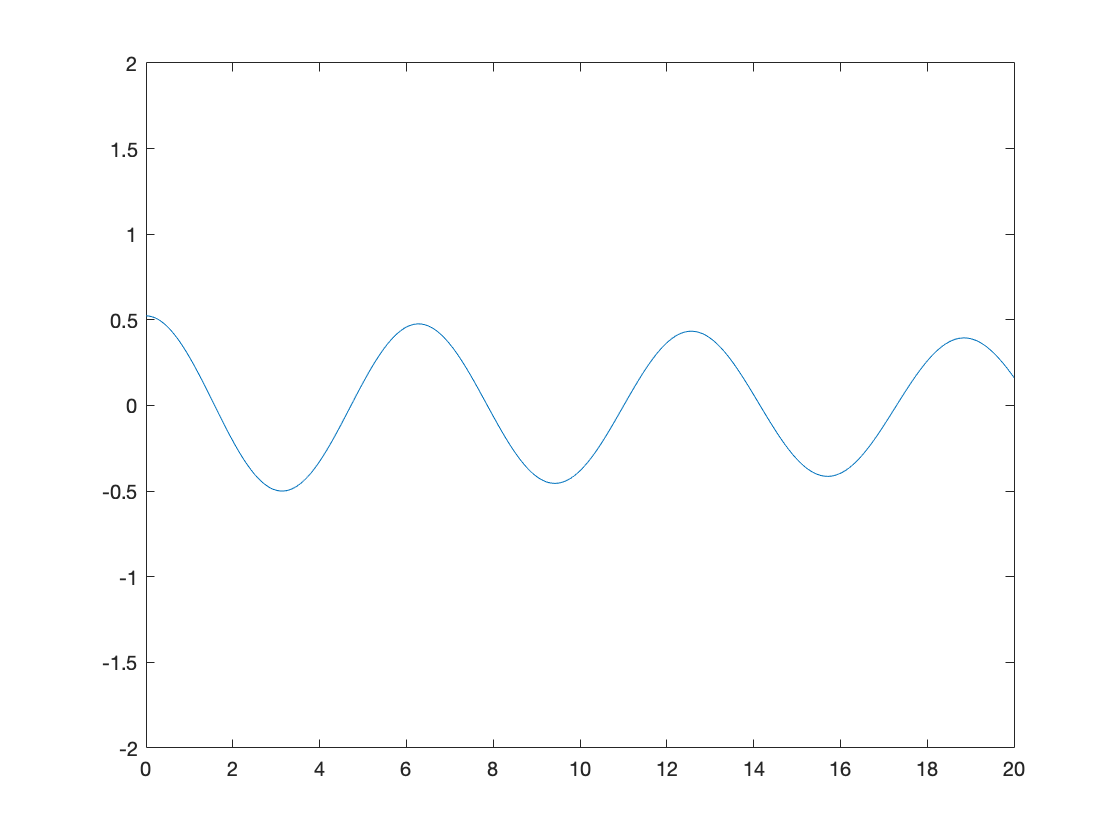

figure
plot(t,thetaphi(1,:))
ylim([-2 2])

**Part (d) (3 points)** We like to animate the trajectory of the pendulum on a horizontal plane. You can plot the horizontal projection of the pendulum by plotting $x_p=L_1\sin(\theta(t))$and $y_p=L_2\sin(\phi(t))$.

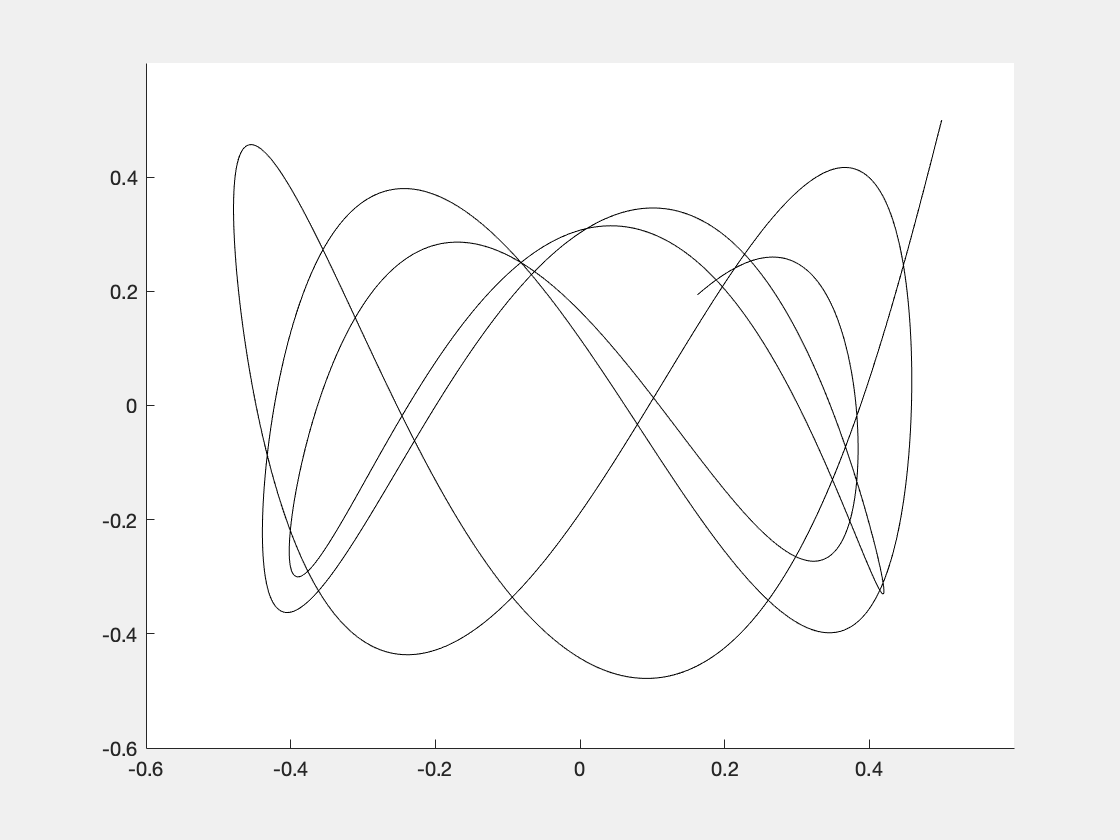

%place your code here:

L1=1;
L2=1;
figure('visible','on')
h = animatedline;
axis([-0.6 0.6 -0.6 0.6])
 for k = 1:length(t)
     addpoints(h,L1*sin(thetaphi(1,k)),L2*sin(thetaphi(2,k)));
     drawnow
 end